clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Three-step with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,1,{[-1,1]},0);

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0496
       solvertime: 0.0034
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           15.9595|       6.597e-16|
|   #2|   Matrix inequality|           28.4742|     -1.9942e-24|
|   #3|   Matrix inequality|            7.6585|      1.7532e-13|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0466
       solvertime: 0.0044
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|            4.7763|      1.8089e-21|
|   #2|        Matrix inequality|             5.107|      7.9983e-22|
|   #3|        Matrix inequality|            6.6085|     -1.7381e-25|
|   #4|        Matrix inequality|            2.6708|      5.9303e-21|
|   #5|   Elementwise inequality|           67.0083|     -1.1213e-20|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

P_min =    22.8009   -3.2843    7.1136         0         0         0         0         0         0         0         0         0
   -3.2843    5.9211    3.5386         0         0         0         0         0         0         0         0         0
    7.1136    3.5386   20.3087         0         0         0         0         0         0         0         0         0
         0         0         0   22.2723   -3.2030    6.9715         0         0         0         0         0         0
         0         0         0   -3.2030    5.8035    3.4445         0         0         0         0         0         0
         0         0         0    6.9715    3.4445   19.9570         0         0         0         0         0         0
         0         0         0         0         0         0   21.9461   -3.1703    6.8786         0         0         0
         0         0         0         0         0         0   -3.1703    5.8125    3.4336         0         0         0
         0         0    

ans =   -77.5538
   10.9237
   -8.6455
  -78.7971
  -76.5664
  -77.3040
   10.8736
    9.7998
   10.1026
   -8.7504


ans =   -63.8183
  -63.6121
  -63.6099
  -63.4943
  -12.5291
  -12.5217
  -12.0414
  -11.8126
   -5.5020
   -5.4394


ans =  -240.7059
 -226.6168
 -199.6763
 -125.7201
  -19.3947
  -20.8799
  -21.4012
  -12.8482
   -4.5946
   -6.4814


ans =  -105.4105
 -103.0035
  -97.7754
  -71.7401
  -29.6694
  -24.8032
  -23.7563
  -22.9238
   -7.2138
   -6.8541


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0421
       solvertime: 0.0019
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


ans = 112.1265

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0425
       solvertime: 0.0085
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|         6.406e-12|       2.906e-11|
|   #2|   Matrix inequality|        -1.549e-09|      2.8755e-11|
|   #3|   Matrix inequality|        2.6514e-09|      3.0002e-11|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 
Evaluation of des

ans =   -3.5774 + 0.0000i  -0.2298 + 0.4800i  -0.2298 - 0.4800i  -3.6376 + 0.0000i  -0.2189 + 0.4980i  -0.2189 - 0.4980i  -3.5293 + 0.0000i  -0.2538 + 0.4487i  -0.2538 - 0.4487i  -3.5281 + 0.0000i  -0.2544 + 0.4597i  -0.2544 - 0.4597i


Eigenvalues of the coupled systems are all negative 


ans =   -3.1670 + 0.0000i  -2.8564 + 0.0000i  -2.7798 + 0.0000i  -2.4744 + 0.0000i  -0.4618 + 0.6079i  -0.4618 - 0.6079i  -0.5968 + 0.7039i  -0.5968 - 0.7039i  -0.6151 + 0.6228i  -0.6151 - 0.6228i  -0.7807 + 0.5618i  -0.7807 - 0.5618i


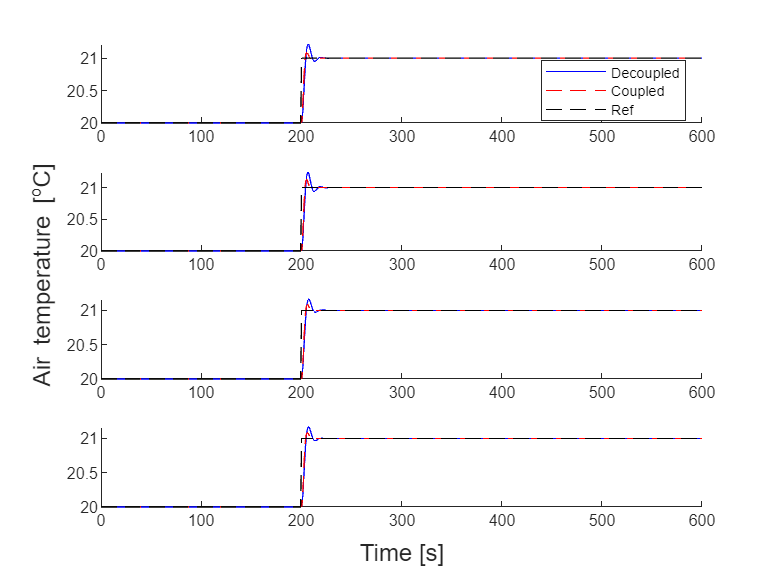

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha0",0);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 1.7280

ans =     0.2351
    0.2386
    0.2411
    0.2411
    0.3188
    0.3387
    0.3623
    0.3632
    0.9392
    0.9545


ans =     1.8708   -0.2645    0.2885         0         0         0         0         0         0         0         0         0   -0.3470   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.2645    0.4444    0.1069         0         0         0         0         0         0         0         0         0   -0.1931    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2885    0.1069    0.4499         0         0         0         0         0         0         0         0         0   -0.2493   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
         0         0         0    1.6578   -0.2569    0.2334         0         0         0         0         0         0    0.0000   -0.3229   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
         0         0         0   -0.2569    0.4357    0.1013         0         0         0         0         0         0   -0.0000   -0.1950    0.0000   -0.0000   -0.0000   -0.0000    0.0000

P_out =     1.8708   -0.2645    0.2885         0         0         0         0         0         0         0         0         0   -0.3470   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.2645    0.4444    0.1069         0         0         0         0         0         0         0         0         0   -0.1931    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2885    0.1069    0.4499         0         0         0         0         0         0         0         0         0   -0.2493   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
         0         0         0    1.6578   -0.2569    0.2334         0         0         0         0         0         0    0.0000   -0.3229   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
         0         0         0   -0.2569    0.4357    0.1013         0         0         0         0         0         0   -0.0000   -0.1950    0.0000   -0.0000   -0.0000   -0.0000    0.00

## Three-step with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},-.4);

P_min =    19.6258   -4.7644    2.7912         0         0         0         0         0         0         0         0         0
   -4.7644    7.4580    1.9682         0         0         0         0         0         0         0         0         0
    2.7912    1.9682   18.0991         0         0         0         0         0         0         0         0         0
         0         0         0   17.8601   -4.7603    2.2927         0         0         0         0         0         0
         0         0         0   -4.7603    7.1160    1.7400         0         0         0         0         0         0
         0         0         0    2.2927    1.7400   16.7743         0         0         0         0         0         0
         0         0         0         0         0         0   17.2162   -4.7019    2.1896         0         0         0
         0         0         0         0         0         0   -4.7019    7.0987    1.7021         0         0         0
         0         0    

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -4.0025 + 0.0000i  -0.0173 + 0.0586i  -0.0173 - 0.0586i  -4.0320 + 0.0000i  -0.0217 + 0.1141i  -0.0217 - 0.1141i  -3.9921 + 0.0000i  -0.0225 + 0.1218i  -0.0225 - 0.1218i  -3.9907 + 0.0000i  -0.0231 + 0.1262i  -0.0231 - 0.1262i


Eigenvalues of the coupled systems are all negative 


ans =   -4.0173 + 0.0000i  -3.9985 + 0.0000i  -3.9773 + 0.0000i  -3.9710 + 0.0000i  -0.0192 + 0.0868i  -0.0192 - 0.0868i  -0.0281 + 0.1641i  -0.0281 - 0.1641i  -0.0330 + 0.1932i  -0.0330 - 0.1932i  -0.0308 + 0.1809i  -0.0308 - 0.1809i


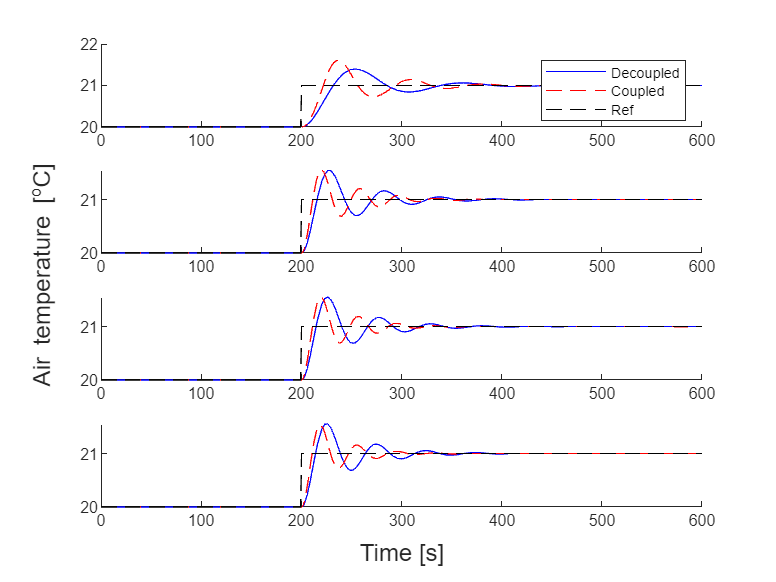

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha",0);

## ILMI algorithm


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF_ILMI(param,0,{[-1,1]});

alpha_min = 0.1675

alpha_min = -0.0874

Evaluation of design procedure for ILMI SOF 
Solved the problem in 2 iterations
The solution had alpha: -0.087372 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.5386   -0.4112   -0.0872   -3.5731   -0.3998   -0.1025   -3.5264   -0.3993   -0.1112   -3.5092   -0.4261   -0.1015


Eigenvalues of the coupled systems are all negative 


ans =   -3.0458 + 0.0000i  -2.5568 + 0.0000i  -2.3891 + 0.0000i  -0.9089 + 0.0000i  -1.9714 + 0.2443i  -1.9714 - 0.2443i  -1.3958 + 0.0000i  -1.5860 + 0.0000i  -0.0800 + 0.0000i  -0.0980 + 0.0000i  -0.0920 + 0.0000i  -0.0910 + 0.0000i


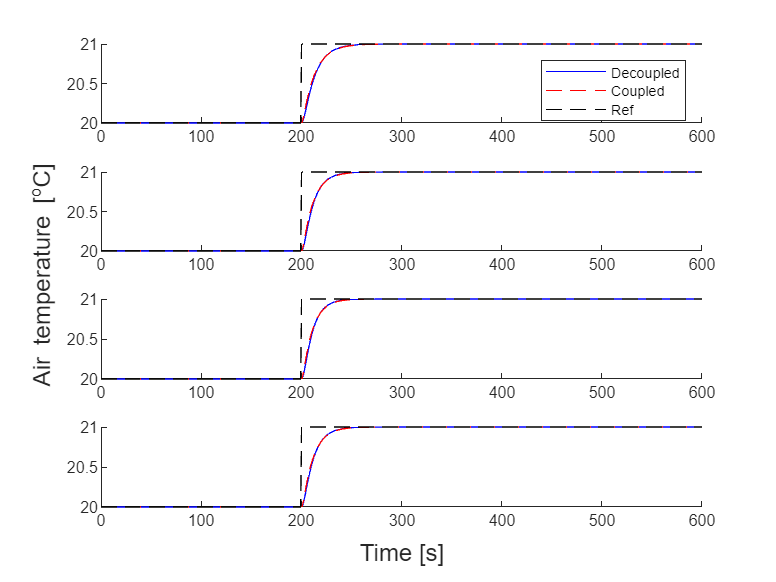

util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI",0);